close all;  clear; clc

S = readmatrix('heart_train.csv','Delimiter',',','DecimalSeparator','.');

% 297 Patients
% 13 Atributos/Features
% 1 (último) Target
size(S);

% Na matriz S, vai buscar todas as linhas (: isolados)
p = S(:,1:end-1)';
t = S(:,end)';

% criar a rede
net = feedforwardnet([10 10 10]);

% treinar a rede
net.divideFcn = '';
[net,tr] = train(net,p,t);

view(net)

%
y = net(p);

% mostrar o resultado
y = (y >= 0.5);
accuracy = sum(y==t)/length(t);
disp(['Accuracy = ' num2str(accuracy)]);

Accuracy = 1


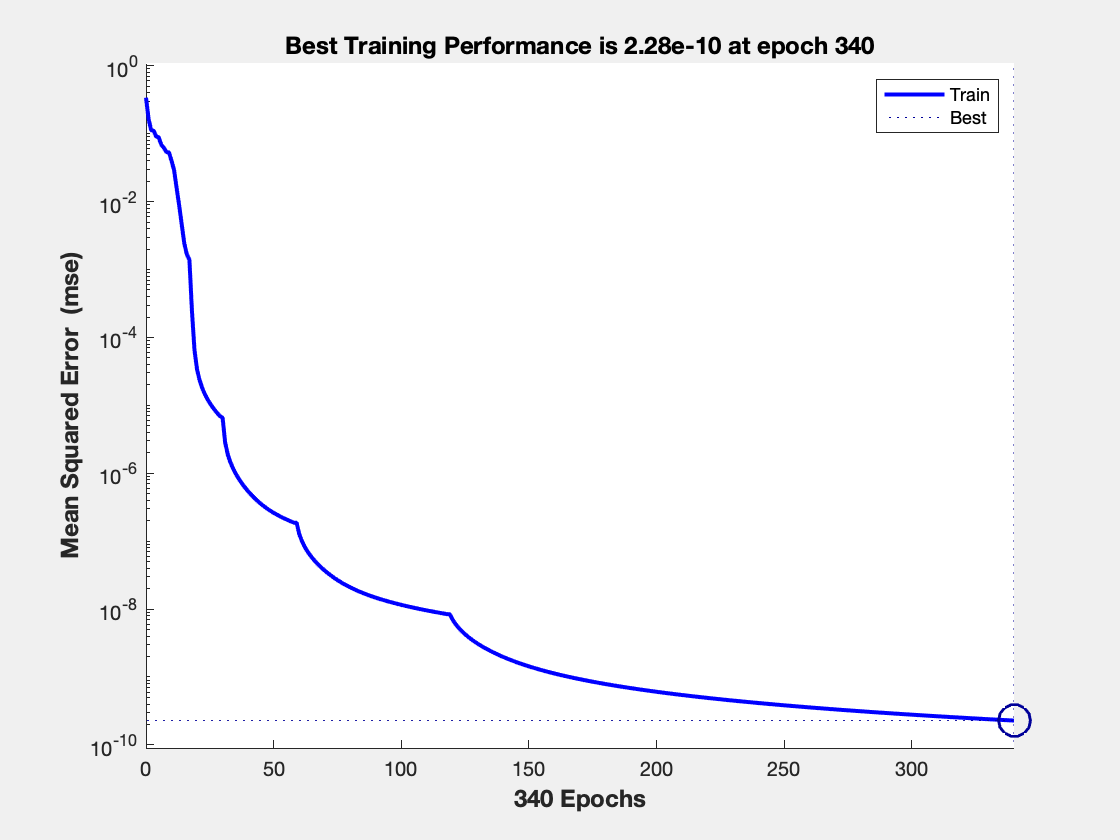

plotperform(tr);


disp(t);

  Columns 1 through 21

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 22 through 42

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 43 through 63

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 64 through 84

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 85 through 105

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 106 through 126

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 127 through 147

     1     1     1     1     1     1     1     1     


save('nn_heart1.mat','net');